% Load recorded data for sitting, supine, and standing positions
sitting_data = readtable('F:\IITM\Mtech 2_sem\Advanced_BME_lab\4thMar2024_ECG_PPG_GroupB\4thMar2024\kavi_sit.csv');
supine_data = readtable('F:\IITM\Mtech 2_sem\Advanced_BME_lab\4thMar2024_ECG_PPG_GroupB\4thMar2024\kavi.csv');
standing_data = readtable('F:\IITM\Mtech 2_sem\Advanced_BME_lab\4thMar2024_ECG_PPG_GroupB\4thMar2024\kavi_st.csv');

% Sample rate (replace with your sample rate)
fs = 200; % Sample rate in Hz

% Process data and calculate HRV metrics for each position
[sitting_rmssd, sitting_sdnn, sitting_pnn50, sitting_hr] = process_and_calculate_hrv(sitting_data, fs);
[supine_rmssd, supine_sdnn, supine_pnn50, supine_hr] = process_and_calculate_hrv(supine_data, fs);

[standing_rmssd, standing_sdnn, standing_pnn50, standing_hr] = process_and_calculate_hrv(standing_data, fs);

% Calculate pulse rate and PRV for each position
[sitting_pulse_rate, sitting_prv] = calculate_pulse_rate_prv(sitting_data, fs);
[supine_pulse_rate, supine_prv] = calculate_pulse_rate_prv(supine_data, fs);
[standing_pulse_rate, standing_prv] = calculate_pulse_rate_prv(standing_data, fs);

% Display results
disp('HRV Metrics, Heart Rate, Pulse Rate, and PRV Comparison:');

HRV Metrics, Heart Rate, Pulse Rate, and PRV Comparison:


disp(['Sitting Position - RMSSD: ', num2str(sitting_rmssd), ' seconds, SDNN: ', num2str(sitting_sdnn), ' seconds, PNN50: ', num2str(sitting_pnn50), '%, HR: ', num2str(sitting_hr), ' bpm, Pulse Rate: ', num2str(sitting_pulse_rate), ' bpm, PRV: ', num2str(sitting_prv), ' seconds']);

Sitting Position - RMSSD: 0.14261 seconds, SDNN: 0.14308 seconds, PNN50: 26.3823%, HR: 588.1078 bpm, Pulse Rate: 524.2086 bpm, PRV: 0.11034 seconds


disp(['Supine Position - RMSSD: ', num2str(supine_rmssd), ' seconds, SDNN: ', num2str(supine_sdnn), ' seconds, PNN50: ', num2str(supine_pnn50), '%, HR: ', num2str(supine_hr), ' bpm, Pulse Rate: ', num2str(supine_pulse_rate), ' bpm, PRV: ', num2str(supine_prv), ' seconds']);

Supine Position - RMSSD: NaN seconds, SDNN: NaN seconds, PNN50: NaN%, HR: NaN bpm, Pulse Rate: 678.3626 bpm, PRV: 0.059821 seconds


disp(['Standing Position - RMSSD: ', num2str(standing_rmssd), ' seconds, SDNN: ', num2str(standing_sdnn), ' seconds, PNN50: ', num2str(standing_pnn50), '%, HR: ', num2str(standing_hr), ' bpm, Pulse Rate: ', num2str(standing_pulse_rate), ' bpm, PRV: ', num2str(standing_prv), ' seconds']);

Standing Position - RMSSD: 0.67598 seconds, SDNN: 0.4906 seconds, PNN50: 31.0078%, HR: 427.5456 bpm, Pulse Rate: 711.3573 bpm, PRV: 0.054041 seconds


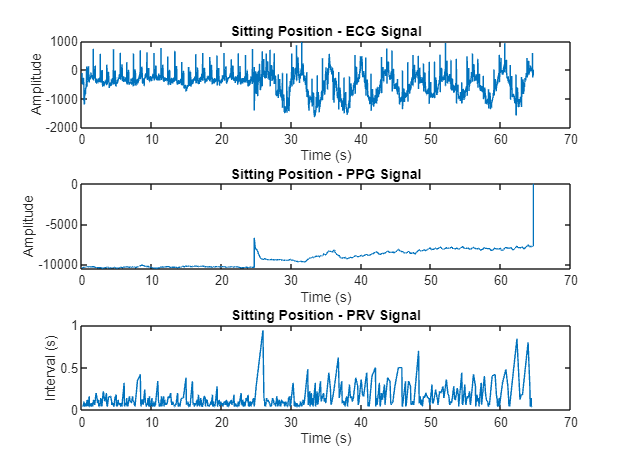


% Plot ECG, PPG, and PRV signals for sitting position
plot_signals_comparison(sitting_data, 'Sitting Position', fs);

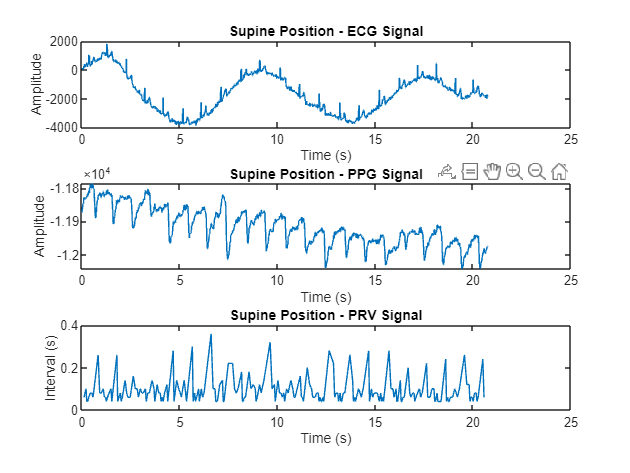


% Plot ECG, PPG, and PRV signals for supine position
plot_signals_comparison(supine_data, 'Supine Position', fs);

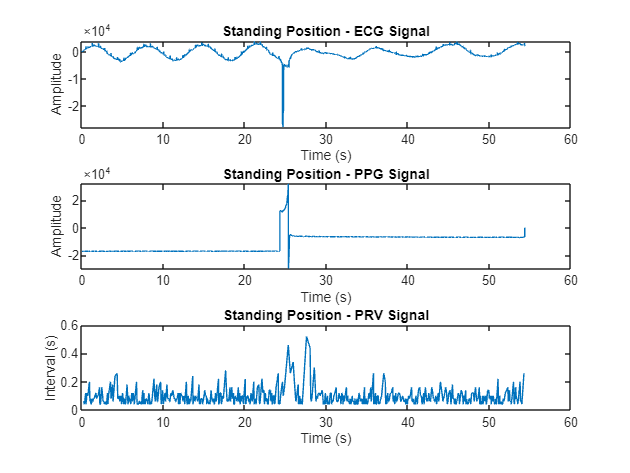


% Plot ECG, PPG, and PRV signals for standing position
plot_signals_comparison(standing_data, 'Standing Position', fs);


% Function to process data and calculate HRV metrics

function [rmssd, sdnn, pnn50, hr] = process_and_calculate_hrv(data, fs)
    % Extract ECG signal
    ecg_signal = data{:, 2}; % Assuming ECG data is in the second column
    
    % Convert to numeric array
    ecg_signal = double(ecg_signal);
    
    % Compute RR intervals from ECG signal
    [~, r_locs_ecg] = findpeaks(ecg_signal, 'MinPeakHeight', mean(ecg_signal));
    rr_intervals_ecg = diff(r_locs_ecg) / fs; % RR intervals in seconds for ECG
    
    % Compute RMSSD from RR intervals for ECG
    rmssd = sqrt(mean(diff(rr_intervals_ecg).^2)); % RMSSD for ECG
    
    % Compute SDNN from RR intervals for ECG
    sdnn = std(rr_intervals_ecg); % SDNN for ECG
    
    % Compute PNN50 from RR intervals for ECG
    pnn50 = sum(abs(diff(rr_intervals_ecg)) > 0.05) / length(rr_intervals_ecg) * 100; % PNN50 for ECG
    
    % Compute heart rate from RR intervals for ECG
    hr = 60 / mean(rr_intervals_ecg); % Heart rate in bpm
end

% Function to calculate pulse rate and PRV from PPG signal
function [pulse_rate, prv] = calculate_pulse_rate_prv(data, fs)
    % Extract PPG signal
    ppg_signal = data{:, 3}; % Assuming PPG data is in the third column
    
    % Convert to numeric array
    ppg_signal = double(ppg_signal);
    
    % Find peaks in PPG signal
    [~, ppg_peaks_locs] = findpeaks(ppg_signal);
    
    % Calculate pulse rate
    pulse_intervals = diff(ppg_peaks_locs) / fs; % Time intervals between pulses
    pulse_rate = 60 / mean(pulse_intervals); % Pulse rate in bpm
    
    % Calculate PRV
    prv = std(pulse_intervals); % PRV in seconds
end

% Function to plot ECG, PPG, and PRV signals
function plot_signals_comparison(data, position, fs)
    % Extract ECG and PPG signals
    ecg_signal = double(data{:, 2}); % Assuming ECG data is in the second column
    ppg_signal = double(data{:, 3}); % Assuming PPG data is in the third column
    
    % Compute time vector
    t_ecg = (0:length(ecg_signal)-1) / fs;
    t_ppg = (0:length(ppg_signal)-1) / fs;
    
    % Plot ECG signal
    figure;
    subplot(3, 1, 1);
    plot(t_ecg, ecg_signal);
    title([position ' - ECG Signal']);
    xlabel('Time (s)');
    ylabel('Amplitude');
    
    % Plot PPG signal
    subplot(3, 1, 2);
    plot(t_ppg, ppg_signal);
    title([position ' - PPG Signal']);
    xlabel('Time (s)');
    ylabel('Amplitude');
    
    % Calculate and plot PRV signal
    [~, ppg_peaks_locs] = findpeaks(ppg_signal);
    pulse_intervals = diff(ppg_peaks_locs) / fs;
    t_prv = (ppg_peaks_locs(2:end) - 1) / fs;
    
    subplot(3, 1, 3);
    plot(t_prv, pulse_intervals);
    title([position ' - PRV Signal']);
    xlabel('Time (s)');
    ylabel('Interval (s)');
end

